# Final Assignment 5SMB0

## Part 1: Understanding saturation and Butterworth filter

1.1 (3 points) The (partially) known parts of the system consist of F(q) and S. De termine by an initial experiment the parameter M and explain what influence F(q) and S will have on the identification of the unknown part H and G. This could be, e.g., on the remaining steps of the system identification cycle, limitations on the obtained final model, etc.

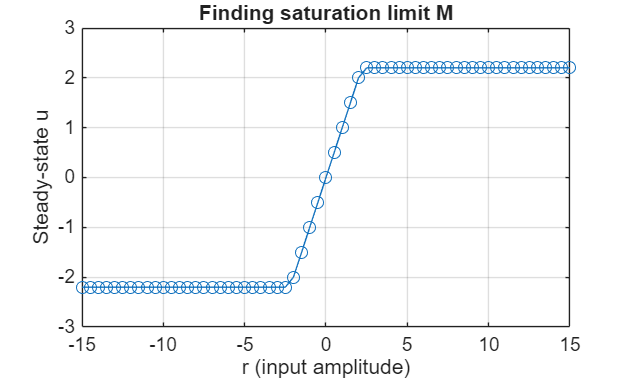

N = 500;
mode = 'open loop';

amplitudes = -15:0.5:15;
u_steady = zeros(size(amplitudes));

% loop over amplitudes and find steady state using the last 20 samples
for i = 1:length(amplitudes)
    r = amplitudes(i) * ones(N, 1);
    [u, f] = assignment_sys_14(r, mode);
    u_steady(i) = mean(u(end-20:end)); 
end
   
figure;
plot(amplitudes, u_steady, 'o-');
xlabel('r (input amplitude)'); 
ylabel('Steady-state u');
title('Finding saturation limit M');
grid on;

When looking at the graph we can duduce that the parameter M saturates at a steady state input above 2.2

## Part 2: Nonparametric identification

2.1 (4 points) We first want to get a rough idea of the frequency behavior of G0(q). To this end, we want to perform a preliminary experiment and apply nonparametric system identification using the collected data. The task is then to design an experiment of length N =1500. What type of reference shall be used? Give an expression of r(k) and motivate your choice.

Transient Detection

clear; clc; close all;
% inspiration from A2_MultisineDesign.mlx
fs = 1; % Hz
N = 1500; % Number of samples
P = 5; % P > 2, see slides lecture 3
Np = N / P % sampeling period

Np = 300


Ts = 1/fs;  % sampling interval in seconds
f0 = fs/Np;  % the frequency resolution in Hz

fmin = 0.1; % lowest excited frequency in Hz - should be larger than 0 and smaller than fmax
fmax = fs/2 -0.05;   % highest excited frequency in Hz - should be lower than the nyquist frequency fs/2
% fmax = 0.35

t = (0:1:N-1)*Ts; % time vector in sec. we start at 0, so we need to stop at N*Ts-Ts to have a total of N samples
f = (0:1:N-1)*f0; % frequency vector in Hz

nmin = ceil(fmin/f0);  % the frequency bin of the lowest excited frequency
nmax = floor(fmax/f0); % the frequency bin of the highest excited frequency
bins = nmin:nmax; % vector containing the excited frequency bins

A = zeros(1,Np/2-1); 
A(bins+1)=1; % constant amplitude on the excited frequency bins, zero elsewhere

phi = zeros(1,Np/2-1); 
phi(bins+1) = 2*pi*rand(1,nmax-nmin+1); % random phases, uniformly distributed between 0 and 2pi

U = zeros(1, Np); 
U(bins+1) = A(bins+1) .* exp(1i*phi(bins+1)); 
r_period = real(ifft(U*Np)); % transform back to time domain

safe_amplitude = 1.5;
r_period = safe_amplitude * (r_period / max(abs(r_period))); 
r_period = r_period(:); 

r = repmat(r_period, P, 1);

mode = 'open loop';
[u, y] = assignment_sys_14(r, mode);

u_max = max(abs(u))

u_max = 1.0501

2.2 (4 points) Identify an FRF of the system. Motivate the chosen FRF estimator. What can we conclude from this FRF? Think of, e.g., high-frequency behavior, gain, res onance peaks, etc.

% put time domain data into matrices, each column is one period
u_matrix = reshape(u, Np, P);
y_matrix = reshape(y, Np, P);

% throw away first 2 periods to prevent leakage
u_ss = u_matrix(:, 2:end);
y_ss = y_matrix(:, 2:end);

% number of steady state periods
P_ss = P - 1;

% transform steady state to frequency domain
U_freq = fft(u_ss);
Y_freq = fft(y_ss);

% Maximum likelyhood FRF estimator => mean of output / mean of input
U_mean = mean(U_freq, 2);
Y_mean = mean(Y_freq, 2);

G_FRF = Y_mean ./ U_mean

G_FRF = 1.0e+13 *

   2.5326 + 0.0000i
  -0.3273 - 0.2179i
   0.0940 - 0.1929i
   0.8300 - 0.4466i
  -0.1613 - 0.1585i
  -0.1519 - 0.0438i
   0.2986 + 0.0382i
  -0.4165 + 0.3161i
  -0.0918 - 0.8396i
  -0.2700 - 0.0231i
  -0.2111 - 0.0194i
   0.1666 + 0.1628i
   0.3795 + 0.3862i
   0.2212 + 0.4605i
   0.1312 + 0.7588i


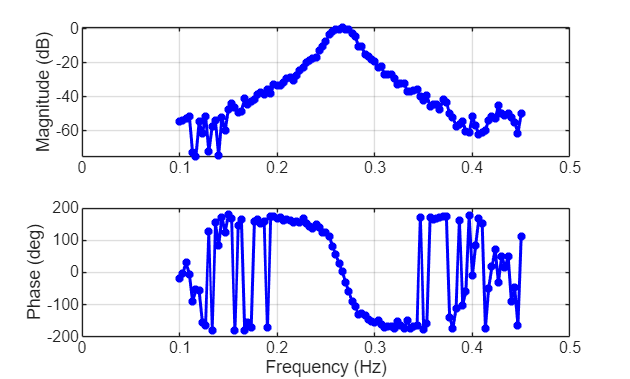


% make freq axis
freqs_hz = (0:Np-1)' * f0;
Nyquist_idx = floor(Np/2);

% only use excited frequencies
excited_indices = bins + 1;

% extract only the meaningful data
freqs_excited = freqs_hz(excited_indices);
G_FRF_excited = G_FRF(excited_indices);

% calculate Magnitude in dB
G_magnitude_dB = 20 * log10(abs(G_FRF_excited));
G_phase_deg = (angle(G_FRF_excited)) * (180/pi);

figure()
subplot(2,1,1);
plot(freqs_excited, G_magnitude_dB, 'b*-', 'LineWidth', 1.5, 'MarkerSize', 4);
ylabel('Magnitude (dB)');
xlim([0, 0.5]); grid on;

subplot(2,1,2);
plot(freqs_excited, G_phase_deg, 'b*-', 'LineWidth', 1.5, 'MarkerSize', 4);
xlabel('Frequency (Hz)');
ylabel('Phase (deg)');
xlim([0, 0.5]); grid on;

2.3 (4 points) Use the data generated in Part 2.1 to obtain an estimation of the non parametric noise model, i.e., derive an expression for estimating the noise spectrum Φv and plot the magnitude of the estimated noise power spectrum. What can you conclude from the estimated spectrum?

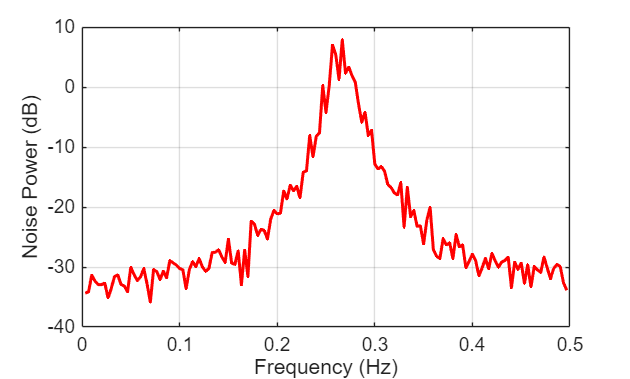

% calculate sample variance
Phi_v = var(Y_freq, 0, 2);

% power is mag^2 so use 10*log10 :)
Phi_v_dB = 10 * log10(abs(Phi_v));

% plot als freq up to niquist excluding 0 Hz
plot_indices = 2:Nyquist_idx;

figure()
plot(freqs_hz(plot_indices), Phi_v_dB(plot_indices), 'r-', 'LineWidth', 1.5);
xlabel('Frequency (Hz)'); 
ylabel('Noise Power (dB)');
xlim([0, 0.5]);
grid on;

If we compare the Bode plot (G) and the power specrtum (H), they bot look very similair in magnitude behaivior. Both have a resonance peak at 0.27 Hz. This suggest that th noise has similair/ the same poles as the system G.

## Part 3: Parametric identification and validation

3.1 (4 points) Based on the findings of the nonparametric identification, we want to get a parametric model of G0(q). Design a new experiment of length N = 3000. Choose a signal type of r(k) and motivate your choice.

The plots from part 2 suggest that th noise has similair/ the same poles as the system G. This means that we deal with an ARX/ ARMAX model structure (see lecture 6 slide 8).

clear; clc; close all;
N = 3000 % Number of samples

N = 3000

fs = 1; % Hz
fn = fs/ 2;
Ts = 1/fs;  % sampling interval in seconds

% make a random gaussian white noise sequence N samples long
r_white_noise = randn(N, 1);

% point of interest is 0.27 Hz, so like in lecture 9 we filter to only see
% the region of interest
wn = [0.15/fn, 0.35/fn]; % normalize with the niquist freq
[b, a] = butter(6, wn, 'bandpass'); % check if n is sufficient
r_filtered = filtfilt(b, a, r_white_noise); % filter

% scale r to avoid saturation (M = 2.2)
safe_amplitude = 1.5;
r = safe_amplitude * (r_filtered / max(abs(r_filtered))); 

mode = 'open loop';
[u, y] = assignment_sys_14(r, mode);

u_max = max(abs(u))

u_max = 1.4502

3.2 (8 points) Using the designed input from Part 3.1, perform parametric identification of the system that yields a consistent estimate of G0. Motivate the choices that you make for, e.g., the model structure, model orders, validation methods, etc. Finally, compare the obtained results with the results from Part 2.

data = iddata(y, u, Ts);

% split data in train and test set
x_train = data(1:1500);
x_test = data(1501:3000);

delay = delayest(x_train)

delay = 4

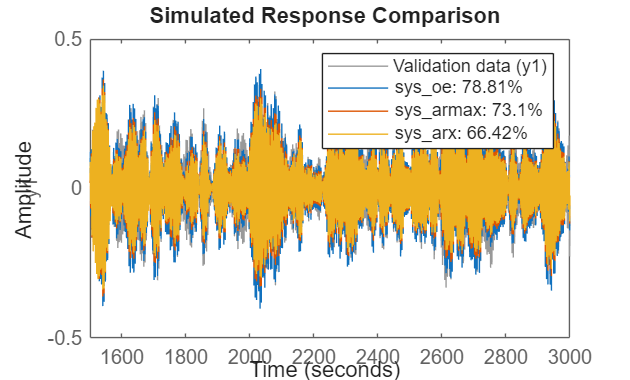


% tune these maybe
na = 6; % na is the order of the polynomial A(q)
nb = 6; % nb is the order of the polynomial B(q) + 1
nc = 8; % nc is the order of the polynomial C(q)
nk = delay; % nk is the input-output delay

% define systems
sys_arx = arx(x_train, [na, nb, nk]);
sys_armax = armax(x_train, [na, nb, nc, nk]);
sys_oe = oe(x_train, [na, nb, nk]);

compare(x_test, sys_oe, sys_armax, sys_arx);

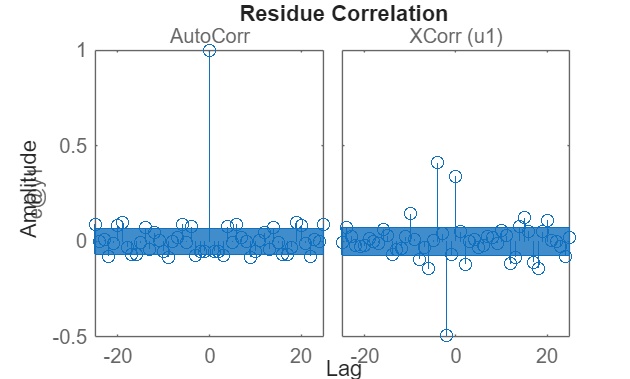


figure();
resid(x_test, sys_arx);

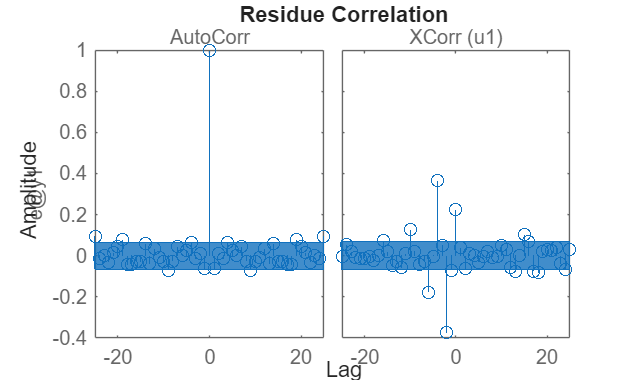


figure();
resid(x_test, sys_armax);

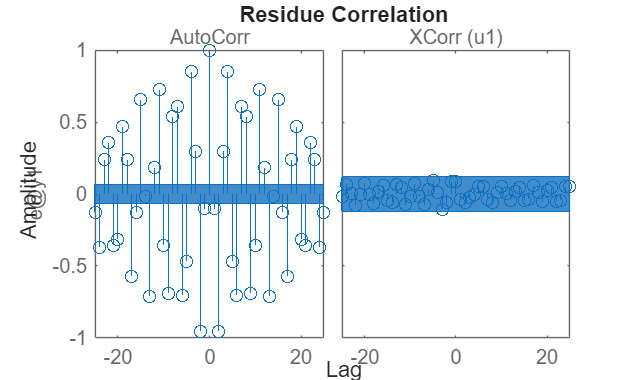


figure();
resid(x_test, sys_oe); % highly auto corr

## Part 4: Experimental verification of variance estimates

4.1 (4 points) We would like to get an understanding of the mechanism behind the estimation of the variance of identified parameters. To this end, we are going to introduce experiment repetition as a way to estimate the variance of an estimated model. We do this by performing Monte Carlo simulations, that is, repeating Question 3 for 100 times. Inspect the parameters obtained from the Monte Carlo simulations. Do we always get similar results from the different simulation runs? If not, could you explain why?

clear; clc; close all;
N = 3000 % Number of samples

N = 3000

fs = 1; % Hz
fn = fs/ 2;
Ts = 1/fs;  % sampling interval in seconds
runs = 100 % monte carlo iterations

runs = 100


na = 6; % na is the order of the polynomial A(q)
nb = 6; % nb is the order of the polynomial B(q) + 1
nc = 8; % nc is the order of the polynomial C(q)
nk = 4; % nk is the input-output delay

% make a random gaussian white noise sequence N samples long
r_white_noise = randn(N, 1);

% point of interest is 0.27 Hz, so like in lecture 9 we filter to only see
% the region of interest
wn = [0.15/fn, 0.35/fn]; % normalize with the niquist freq
[b, a] = butter(6, wn, 'bandpass'); % check if n is sufficient
r_filtered = filtfilt(b, a, r_white_noise); % filter

% scale r to avoid saturation (M = 2.2)
safe_amplitude = 1.5;
r = safe_amplitude * (r_filtered / max(abs(r_filtered))); 

mode = 'open loop';

for i = 1:runs
    [u, y] = assignment_sys_14(r, mode);
    data = iddata(y, u, Ts);

    sys_mc = armax(data, [na, nb, nc, nk]);
    A_params(i, :) = sys_mc.A(2:end); % remove the 1 (lecture 5/6)
    B_params(i, :) = sys_mc.B((end - nb + 1):end); % grab last 6 parameters ignore delay 0 

    if mod(i, 10) == 0
        disp("Iteration: " + i + "/ 100")
    end
end

Iteration: 10/ 100
Iteration: 20/ 100
Iteration: 30/ 100
Iteration: 40/ 100
Iteration: 50/ 100
Iteration: 60/ 100
Iteration: 70/ 100
Iteration: 80/ 100
Iteration: 90/ 100
Iteration: 100/ 100



% get cov of the last run
cov_matrix = getcov(sys_mc);
var_A = diag(cov_matrix(1:na, 1:na))';
var_B = diag(cov_matrix(na+1:na+nb, na+1:na+nb))';

% get var of the monte carlo sim
sim_var_A = var(A_params);
sim_var_B = var(B_params);

%%%% how to compare now??






